# **Simulation of Parallel M/M/2 Queue**

**EE6150 - Stochastic Modeling and the Theory of Queues**

**Jayadev Joy (EE18B011) **

***Department of Electrical Engineering, IIT Madras***

*05 November 2021*

*I certify that this experiment submission is my own work and not obtained from any other source.*

## 1. Problem Statement

The objective is to simulate a two queue system, where customers arrive according to a Poisson Process with parameter $\lambda$ and join the first queue with probability $P_1$ and the second queue with probability $P_2 = 1 - P_1$. In the first server, the service time is exponentially distributed with parameter $\mu_1$, whereas in the second queue the service time is exponentially distributed with parameter $\mu_2$.

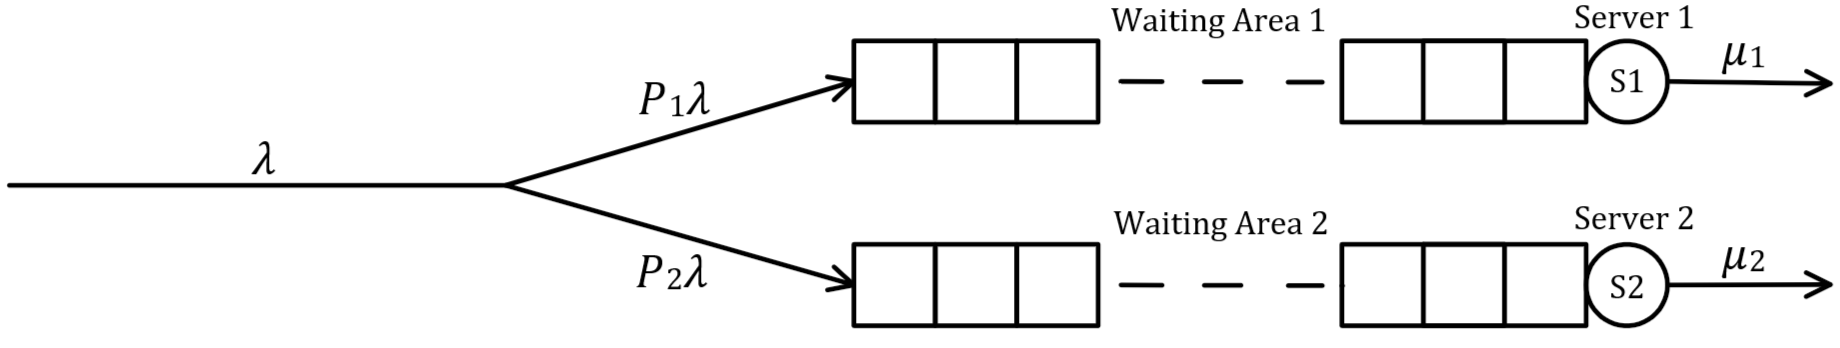

## 2. Initializing the System

In this experiment, I have simulated the above system with the below mentioned values of $P_1$, $P_2$, $\lambda$, $\mu_1$ and $\mu_2$.

lambda = 3;                         % Poisson parameter lambda
prob_1 = 0.2;                       % Probability of joining the first queue
prob_2 = 1 - prob_1;                % Probability of joining the second queue
mu_1 = 5;                           % Exponential Parameter mu1 (Server 1)
mu_2 = 10;                          % Exponential Parameter mu2 (Server 2)
n_cust = 500000;                    % No: of Customers arriving for service
n_cust_1 = round(prob_1*n_cust);    % No: of Customers arriving for service (S1)
n_cust_2 = round(prob_2*n_cust);    % No: of Customers arriving for service (S2)

Now, we will make utilization of the $randperm()$ function to randomly assign $P_1$ fraction of the customers to Server 1 and $P_2$ fraction of the customers to Server 2.

x = randperm(n_cust);                    % Performing random permutation
queue_1 = sort(x(1:(n_cust_1)));         % Assigning P1 fraction of customers to S1
queue_2 = sort(x(end-(n_cust_2)+1:end)); % Assigning P2 fraction of customers to S2

## 3. Arrival and Exit times of the customers

Since customers arrive according to a Poisson Process with parameter $\lambda$, the inter-arrival times would be exponentially distributed with parameter $\lambda$. The function $exprnd()$ can be used to generate the inter-arrival times for all the customers. The arrival times of the customers can be recursively calculated from the inter-arrival times by the formula, $at(i) = at(i-1) + iat(i)$. The information regarding the customers, visiting Servers 1 and 2 have been stored in separate arrays, for convenience. The function $exprnd()$ can also be used to generate the service times for the customers by appropriately changing the parameter value for the 2 servers.

% Generating the Inter-arrival times of the customers
iat = exprnd((1/lambda),1,n_cust);
at = zeros(1,n_cust);   

% Calculating the Arrival times of the customers recursively
at(1) = iat(1);
for i = 2:n_cust
    at(i) = at(i-1) + iat(i);
end

% Storing the arrival times in separate arrays
at_1 = at(queue_1);  % Server 1
at_2 = at(queue_2);  % Server 2

% Generating the Service times of the customers
st_1 = exprnd((1/mu_1),1,n_cust_1);  % Server 1
st_2 = exprnd((1/mu_2),1,n_cust_2);  % Server 2

The calculation of Exit time invloves 2 different cases :

- If the customer did not have to wait, inorder to receive service, then $et(i) = at(i) + st(i)$.

- If the customer had to wait, inorder to receive service, then $et(i)$ can be calculated recursively using $et(i)= et(i-1) + st(i)$.

% Calculating the Exit time of customers in Server 1
et_1 = zeros(1,n_cust_1);
et_1(1) = at_1(1) + st_1(1);
for i = 2:n_cust_1
    et_1(i) = max(at_1(i) + st_1(i), et_1(i-1) + st_1(i));
end

% Calculating the Exit time of customers in Server 2
et_2 = zeros(1,n_cust_2);
et_2(1) = at_2(1) + st_2(1);
for i = 2:n_cust_2
    et_2(i) = max(at_2(i) + st_2(i), et_2(i-1) + st_2(i));
end

## 4. Average values of Response, Waiting and Service Time

### 4.1. Experimentally Obtained Values

The Response time (the total time a customer spends in the system), is the difference between the exit time and the arrival time. The Waiting time (the time a customer spends waiting in the queue), is the difference between the response time and the service time. The average values of these quantities can be calculated using the $mean()$ function.

tt_1 = et_1 - at_1;      % Response time of customers (Server 1)
tt_2 = et_2 - at_2;      % Response time of customers (Server 2)
wt_1 = tt_1 - st_1;      % Waiting time of customers (Server 1)
wt_2 = tt_2 - st_2;      % Waiting time of customers (Server 2)

fprintf(['Experimental Average Response time (Server 1) = %f ' ...
    '\nExperimental Average Response time (Server 2) = %f ' ...
    '\nExperimental Average Waiting time (Server 1) = %f ' ...
    '\nExperimental Average Waiting time (Server 2) = %f ' ...
    '\nExperimental Average Service time (Server 1) = %f ' ...
    '\nExperimental Average Service time (Server 2) = %f'], ...
    mean(tt_1),mean(tt_2),mean(wt_1),mean(wt_2),mean(st_1),mean(st_2));

Experimental Average Response time (Server 1) = 0.227512 
Experimental Average Response time (Server 2) = 0.132321 
Experimental Average Waiting time (Server 1) = 0.027002 
Experimental Average Waiting time (Server 2) = 0.031929 
Experimental Average Service time (Server 1) = 0.200509 
Experimental Average Service time (Server 2) = 0.100392

### 4.2. Theoretically Obtained Values

The formula for Average Response time ($T_i$), Average Waiting time ($W_i$) and Average Service time ($S_i$) for both the servers ($i = 1, 2$) are stated below :


$$T_i = \frac{1}{\mu_i - P_i\lambda}$$
 


$$W_i = \frac{P_i\lambda}{\mu_i(\mu_i - P_i\lambda)}$$



$$S_i = \frac{1}{\mu_i}$$


The Theoretical Average values are calculated using the below code :

ttt_1 = 1/(mu_1-(prob_1*lambda));      % Response time of customers (S1)
ttt_2 = 1/(mu_2-(prob_2*lambda));      % Response time of customers (S2)
twt_1 = (prob_1*lambda*ttt_1)/mu_1;    % Waiting time of customers (S1)
twt_2 = (prob_2*lambda*ttt_2)/mu_2;    % Waiting time of customers (S2)

fprintf(['Theoretical Average Response time (Server 1) = %f ' ...
    '\nTheoretical Average Response time (Server 2) = %f ' ...
    '\nTheoretical Average Waiting time (Server 1) = %f ' ...
    '\nTheoretical Average Waiting time (Server 2) = %f ' ...
    '\nTheoretical Average Service time (Server 1) = %f ' ...
    '\nTheoretical Average Service time (Server 2) = %f'], ...
    ttt_1,ttt_2,twt_1,twt_2,(1/mu_1),(1/mu_2));

Theoretical Average Response time (Server 1) = 0.227273 
Theoretical Average Response time (Server 2) = 0.131579 
Theoretical Average Waiting time (Server 1) = 0.027273 
Theoretical Average Waiting time (Server 2) = 0.031579 
Theoretical Average Service time (Server 1) = 0.200000 
Theoretical Average Service time (Server 2) = 0.100000

### 4.3. Percentage of deviation from the theoretical value

The Percentage of deviation from the theoretical value is calculated using the below code :

% Calculating the Percentage Error in the Experimental results
error_tt_1 = abs(100*(mean(tt_1)-ttt_1)/ttt_1);
error_tt_2 = abs(100*(mean(tt_2)-ttt_2)/ttt_2);
error_wt_1 = abs(100*(mean(wt_1)-twt_1)/twt_1);
error_wt_2 = abs(100*(mean(wt_2)-twt_2)/twt_2);
error_st_1 = abs(100*(mean(st_1)-(1/mu_1))/(1/mu_1));
error_st_2 = abs(100*(mean(st_2)-(1/mu_2))/(1/mu_2));

fprintf(['Percentage of deviation of Average Response time (Server 1) = %f %% ' ...
    '\nPercentage of deviation of Average Response time (Server 2) = %f %% ' ...
    '\nPercentage of deviation of Average Waiting time (Server 1) = %f %% ' ...
    '\nPercentage of deviation of Average Waiting time (Server 2) = %f %% ' ...
    '\nPercentage of deviation of Average Service time (Server 1) = %f %% ' ...
    '\nPercentage of deviation of Average Service time (Server 2) = %f %%'], ...
    error_tt_1,error_tt_2,error_wt_1,error_wt_2,error_st_1,error_st_2);

Percentage of deviation of Average Response time (Server 1) = 0.105166 % 
Percentage of deviation of Average Response time (Server 2) = 0.563905 % 
Percentage of deviation of Average Waiting time (Server 1) = 0.991480 % 
Percentage of deviation of Average Waiting time (Server 2) = 1.109312 % 
Percentage of deviation of Average Service time (Server 1) = 0.254708 % 
Percentage of deviation of Average Service time (Server 2) = 0.391671 %

## 5. Average Number of Customers in the system

The total number of customers in each of the 2 queues at a particular time $t$ can be calculated using the declared function, $n$_$cust$_$sys()$. Details regarding the implementation of $n$_$cust$_$sys()$ will be described towards the end of this report.  

% Defining Time array
time = 0:ceil(max(max(et_1),max(et_2)));

% Number of Customers in Servers 1 and 2 at time t
n_cust_sys_1 = zeros(1,time(end)+1);  % Server 1
n_cust_sys_2 = zeros(1,time(end)+1);  % Server 2

% Calling function n_cust_sys()
for i = time
    n_cust_sys_1(i+1) = n_cust_sys(i,n_cust_1,at_1,et_1);  % Server 1
    n_cust_sys_2(i+1) = n_cust_sys(i,n_cust_2,at_2,et_2);  % Server 2
end

### 5.1. Experimentally Obtained Values

The average number of customers in each of the 2 sub-systems (Server 1 and Server 2) can be obtained by invoking the $mean()$ function.

anc_q1 = mean(n_cust_sys_1) - (nnz(n_cust_sys_1)/length(n_cust_sys_1));
anc_q2 = mean(n_cust_sys_2) - (nnz(n_cust_sys_2)/length(n_cust_sys_2));

fprintf(['Experimental Average Number of Customers (Server 1) = %f ' ...
    '\nExperimental Average Number of Customers (Server 2) = %f' ...
    '\nExperimental Average Number of Waiting Customers in Queue (Server 1) = %f' ...
    '\nExperimental Average Number of Waiting Customers in Queue (Server 2) = %f'], ...
    mean(n_cust_sys_1),mean(n_cust_sys_2),anc_q1,anc_q2);

Experimental Average Number of Customers (Server 1) = 0.136228 
Experimental Average Number of Customers (Server 2) = 0.318889
Experimental Average Number of Waiting Customers in Queue (Server 1) = 0.016214
Experimental Average Number of Waiting Customers in Queue (Server 2) = 0.077426

### 5.2. Theoretically Obtained Values

The formula for Average number of customers in the Queuing System ($N$) and the Average number of waiting customers in the Queuing System ($N_Q$) for both the servers ($i = 1, 2$) are stated below :


$$N_i = \frac{P_i\lambda}{\mu_i - P_i\lambda}$$



$$N_{Qi} = \frac{(P_i\lambda)^2}{\mu_i (\mu_i - P_i\lambda)}$$


The Theoretical Average values are calculated using the below code :

n_sys_1 = prob_1*lambda*ttt_1;  % Average no: of Customers (S1)
n_sys_2 = prob_2*lambda*ttt_2;  % Average no: of Customers (S2)
ancq1 = prob_1*lambda*twt_1;    % Average no: of waiting customers (S1)
ancq2 = prob_2*lambda*twt_2;    % Average no: of waiting customers (S1)

fprintf(['Theoretical Average Number of Customers (Server 1) = %f ' ...
    '\nTheoretical Average Number of Customers (Server 2) = %f' ...
    '\nTheoretical Average Number of Waiting Customers (Server 1) = %f' ...
    '\nTheoretical Average Number of Waiting Customers (Server 2) = %f'], ...
    n_sys_1,n_sys_2,ancq1,ancq2);

Theoretical Average Number of Customers (Server 1) = 0.136364 
Theoretical Average Number of Customers (Server 2) = 0.315789
Theoretical Average Number of Waiting Customers (Server 1) = 0.016364
Theoretical Average Number of Waiting Customers (Server 2) = 0.075789

### 5.3. Percentage of deviation from the theoretical value

The Percentage of deviation from the theoretical value is calculated using the below code :

% Calculating the Percentage Error in the Experimental results
error_ns_1 = abs(100*(mean(n_cust_sys_1)-n_sys_1)/n_sys_1);
error_ns_2 = abs(100*(mean(n_cust_sys_2)-n_sys_2)/n_sys_2);
error_ancq_1 = abs(100*(anc_q1-ancq1)/ancq1);
error_ancq_2 = abs(100*(anc_q2-ancq2)/ancq2);

fprintf(['Percentage of deviation of Average Number of Customers (Server 1) = %f %% ' ...
    '\nPercentage of deviation of Average Number of Customers (Server 2) = %f %%' ...
    '\nPercentage of deviation of Average Number of Waiting Customers (Server 1) = %f %%' ...
    '\nPercentage of deviation of Average Number of Waiting Customers (Server 2) = %f %%'], ...
    error_ns_1,error_ns_2,error_ancq_1,error_ancq_2);

Percentage of deviation of Average Number of Customers (Server 1) = 0.099326 % 
Percentage of deviation of Average Number of Customers (Server 2) = 0.981541 %
Percentage of deviation of Average Number of Waiting Customers (Server 1) = 0.911419 %
Percentage of deviation of Average Number of Waiting Customers (Server 2) = 2.159129 %

## 6. Number of Customers in the system at time t

The Plot of the Number of customers in Queuing System 1 (Server 1) vs Time is provided below:

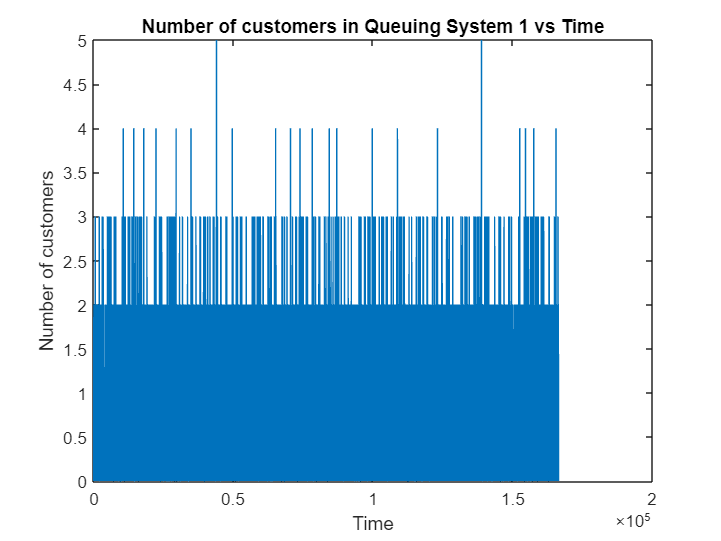

% Number of customers in Queuing System 1 vs Time
figure(1)
plot(time,n_cust_sys_1)
title('Number of customers in Queuing System 1 vs Time')
xlabel('Time')
ylabel('Number of customers')

The Plot of the Number of customers in Queuing System 2 (Server 2) vs Time is provided below:

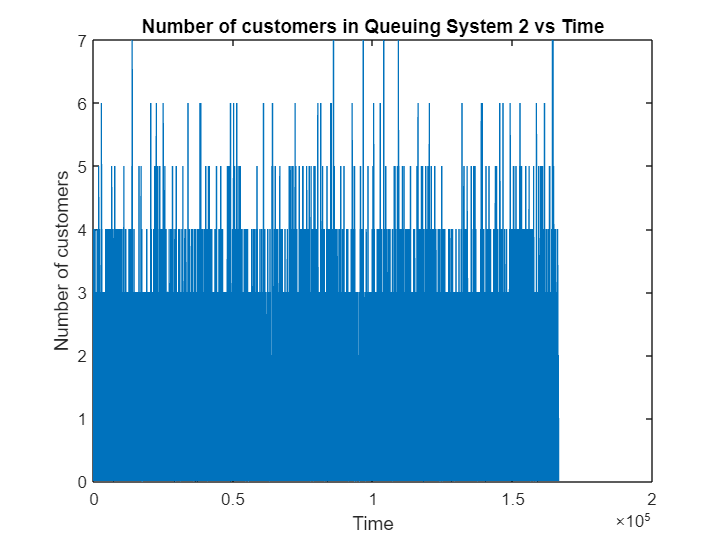

% Number of customers in Queuing System 2 vs Time
figure(2)
plot(time,n_cust_sys_2)
title('Number of customers in Queuing System 2 vs Time')
xlabel('Time')
ylabel('Number of customers')

## 7. Implementation of *n_cust_sys()* function

The function $n$_$cust$_$sys()$ is used to calculate the number of customers in a queuing system at a given time $t$. For a given value of $i$ and $t$, there are 4 logical possibilities (assuming equality does not hold) :

- (arrival time (customer $i$) < $t$) AND (exit time (customer $i$) < $t$) - In this case, customer $i$ has already left and is no longer present in the queuing system at time $t$.

- (arrival time (customer $i$) < $t$) AND (exit time (customer $i$) > $t$) - In this case, customer $i$ is still present in the queuing system at time $t$.

- (arrival time (customer $i$) > $t$) AND (exit time (customer $i$) < $t$) - This case is not physically realizable (Mathematically represents a customer travelling backwards in time).

- (arrival time (customer $i$) > $t$) AND (exit time (customer $i$) > $t$) - In this case, customer $i$ is yet to join the queuing system and is not present at time $t$.

From the above 4 possibilities, it is clear that only case (2) corresponds to the customer $i$ being present in the queuing system at time $t$. This is the condition that we are checking for in the function $n$_$cust$_$sys()$. Assuming that the arrival time and the exit time approaches its specific values from the left hand side, I have included the equality sign in the first condition alone. Equivalently, the equality sign can be included in the second condition alone as well (in which case the arrival time and the exit time approaches its specific values from the right hand side).

function n = n_cust_sys(t,nc,at,et)      % t = time
    ni = 0;                              % nc = Total no: of customers who visited
    for i = 1:nc                         % at = arrival times of customers
        if ((at(i) <= t) && (et(i) > t)) % et = exit times of customers
            ni = ni + 1;
        end
    end
    n = ni;
end

## 8. Observations

- We observe that the experimentally obtained results and the theoretically obtained results (for the chosen values of different parameters and $n\_cust$ and the current execution) are very similar, and the percentage error involved in the experiment is $< 3\%$.

- However, when we choose smaller values for the total number of customers arriving for service (say $n\_cust = 1000$), the errors involved in certain results are observed to become significant (ranging from approximately $15\%$ to $40\%$ in some cases), indicating that the assumptions taken during deriving the formulas need to be revised (for such small values of $n\_cust$).

- Increase in the total number of customers arriving for service ($n\_cust$), results in the reduction in the percentage of error involved in the experimentally obtained results.

- However, such a reduction in the percentage of error (achieved by keeping higher values for $n\_cust$), comes at the cost of an increase in the computation time (running time) of the algorithm.

- We also observe that the experimental results are in accordance with Little’s Law, ie. $N_i=P_i\lambda T_i$.

## 9. References

- EE6150 (Stochastic Modeling and the Theory of Queues) Lecture Notes - *Dr. T.G. Venkatesh*

- Stochastic Processes: Theory for Applications - *Robert G. Gallager*

- Data Networks *- Dimitri P. Bertsekas, Robert G. Gallager*